# Znajdowanie parametrów teczówki – 

# operator różniczkowo-całkowy Daugmana

Zuzanna Rudnicka

249533

Antoni Bezdzietny

249327

#### Przygotowanie ścieżki do zdjęcia.

clear all;
addpath("scripts\daugman\")          
image_folder = "database/image_ir/";
eye         = "007" ;
eye_side    = "1";
eye_variant = "1";
image_path = strcat(image_folder,eye,"/",eye_side,"/",eye,"_",eye_side,"_",eye_variant,".bmp");

#### Wczytanie zdjęcia.

img_gray    = imread(image_path); 

#### Wyświetlenie przetwarzanych obrazów w odcieniach szarości.

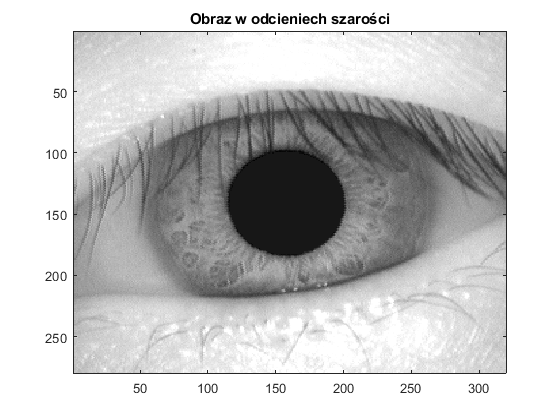

imagesc(img_gray);
title("Obraz w odcieniech szarości");
colormap("gray");

#### `Rozszerzenie detekowanych grawędzi metodą gradientu.`

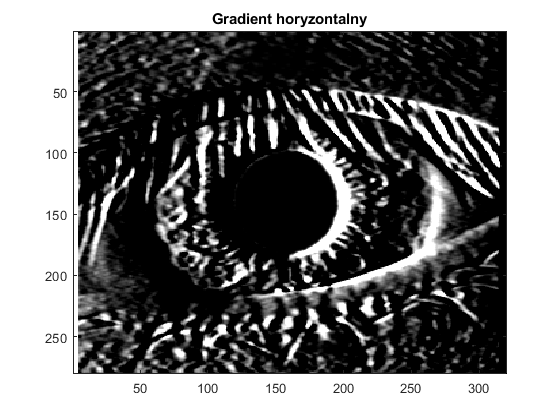

[h_edge, v_edge, image_edge] = FindEdges(img_gray);
image(h_edge);
title("Gradient horyzontalny");

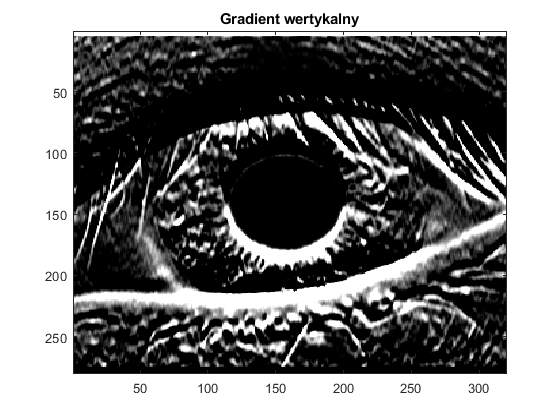

image(v_edge);
title("Gradient wertykalny");

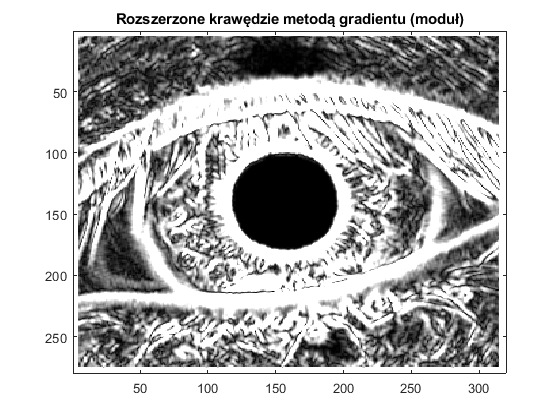

image(image_edge);
title("Rozszerzone krawędzie metodą gradientu (moduł)");

#### Wyszukiwanie okręgów wykorzystując operator różniczkowo-całkowy Daugmana.

- `Wyszukiwanie granicy źrenica-tęczówka.`

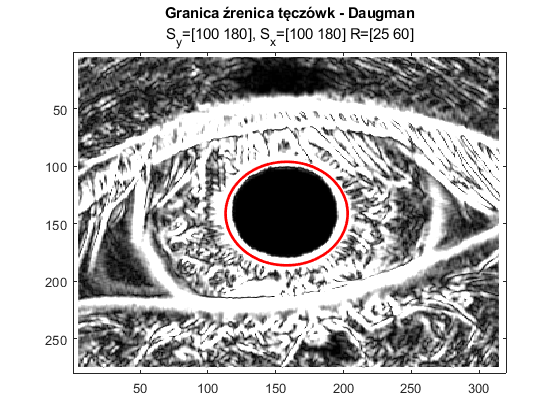

%limits in y (rows)
y_pupil_limits = [150 180];
y_pupil_limits(1) = 100; % lower limits 
y_pupil_limits(2) = 180; % top limits 

%limits in x (cols)
x_pupil_limits = [150 200];
x_pupil_limits(1) = 100; % lower limits 
x_pupil_limits(2) = 180; % top limits 

%limits radius
radius_pupil_limits = [20 60];
radius_pupil_limits(1) = 25; % lower limits 
radius_pupil_limits(2) = 60; % top limits 

dgu = daugmanCircle(image_edge,y_pupil_limits,x_pupil_limits,radius_pupil_limits);

[M,I] = maxk (dgu(:),1);
[ind1, ind2, ind3] = ind2sub(size(dgu),I);
y_pupil = y_pupil_limits(1)+ind1;
x_pupil = x_pupil_limits(1)+ind2;
r_pupil = radius_pupil_limits(1)+ind3;
image(image_edge);
viscircles([x_pupil y_pupil], r_pupil ,'EdgeColor','r');
title("Granica źrenica tęczówk - Daugman", ...
    "S_y=["+num2str(y_pupil_limits(1))+" "+num2str(y_pupil_limits(2))+ ...
    "], S_x=["+num2str(x_pupil_limits(1))+" "+num2str(x_pupil_limits(2))+ ...
    "] R=["+num2str(radius_pupil_limits(1))+" "+num2str(radius_pupil_limits(2))+"]");

- `Wyszukiwanie granicy tęczówka-białko.`

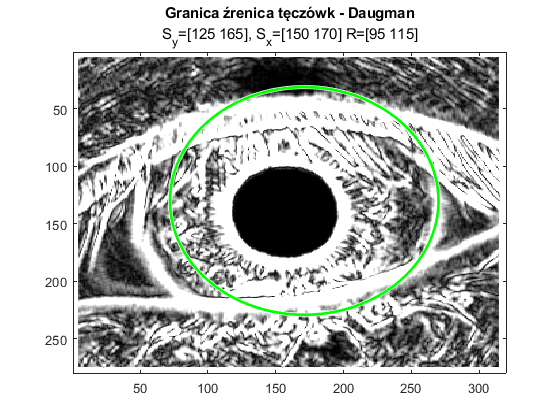

%limits in x (cols)
x_iris_limits = [150 180];
x_iris_limits(1) = 150; % lower limits 
x_iris_limits(2) = 170; % top limits 

%limits in y (rows)
y_iris_limits = [150 180];
y_iris_limits(1) = 125; % lower limits 
y_iris_limits(2) = 165; % top limits 

%limits radius
radius_iris_limits = [80 100];
radius_iris_limits(1) = 95; % lower limits 
radius_iris_limits(2) = 115; % top limits 

dgu = daugmanCircle(image_edge,y_iris_limits,x_iris_limits,radius_iris_limits);

[M,I] = maxk (dgu(:),1);
[ind1, ind2, ind3] = ind2sub(size(dgu),I);
y_iris = y_iris_limits(1)+ind1;
x_iris = x_iris_limits(1)+ind2;
r_iris = radius_iris_limits(1)+ind3;
image(image_edge);
viscircles([x_iris y_iris], r_iris,'EdgeColor','g');
title("Granica źrenica tęczówk - Daugman", ...
    "S_y=["+num2str(y_iris_limits(1))+" "+num2str(y_iris_limits(2))+ ...
    "], S_x=["+num2str(x_iris_limits(1))+" "+num2str(x_iris_limits(2))+ ...
    "] R=["+num2str(radius_iris_limits(1))+" "+num2str(radius_iris_limits(2))+"]");

#### Wykryte granice

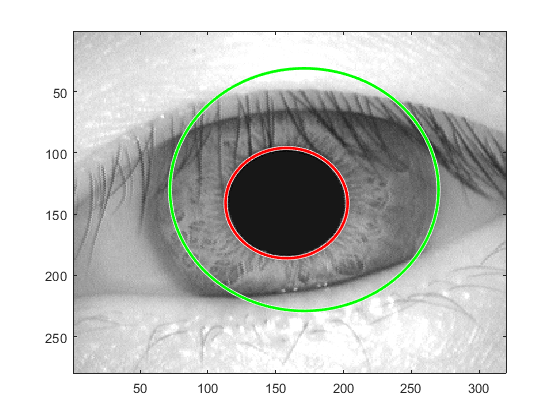

imagesc(img_gray);
viscircles([x_iris y_iris], r_iris,'EdgeColor','g');
viscircles([x_pupil y_pupil], r_pupil ,'EdgeColor','r');